# RBE 501: Coding Forward Kinematics in Robotics Toolkit

## *Build Denso's HSR robot with Robotics Toolkit*

In the prompt of this assignment, we are given the following table.


$$\matrix{
\text{Link}    	& a_i 	& \alpha_i &  d_i & \theta_i  \cr
1			& 205 			& 0	& 220	& \theta_1			\cr
2			& 275 			& 0		& 0	& \theta_2		\cr
3			& 0 			& 0			& d_3 & 0	\cr
4	        & 0 			& 0 		    & 0 & \theta_4					\cr
}$$


To implement this, we first define joint variables.

theta1 = 0;
theta2 = 0;
d3 = 0;
theta4 = 0;

Now, we can import the DH params from the given table.

dhparams = [205   	0   	220   	theta1;
            275	    0       0       theta2;
            0   	0	    d3	    0;
            0       0       0       theta4];

Next, we create a rigid body tree object to build the Denso HSR robot. This is necessary to begin assigning rigid bodies (links) of the robot, to represent moving parts.

denso_robot = rigidBodyTree;

We can begin building the robot now. We make sure that the order of the joints is revolute, revolute, prismatic, revolute. This is because, as shown in the information web-page of Denso Robotics, the HSR robot is essentially a SCARA robot with a revolute tool-tip.

As described in the tutorial of the Robotics Toolkit, we need to assign bodies and joints, as shown in the following code.

body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');
body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
body3 = rigidBody('body3');
jnt3 = rigidBodyJoint('jnt3','prismatic');
body4 = rigidBody('body4');
jnt4 = rigidBodyJoint('jnt4','revolute');

We can then set their transforms (this is done by using rows of the DH table we are given). 

setFixedTransform(jnt1,dhparams(1,:),'dh');
setFixedTransform(jnt2,dhparams(2,:),'dh');
setFixedTransform(jnt3,dhparams(3,:),'dh');
setFixedTransform(jnt4,dhparams(4,:),'dh');

Joints also need to be associated with their bodies, as shown in the following code.

body1.Joint = jnt1;
body2.Joint = jnt2;
body3.Joint = jnt3;
body4.Joint = jnt4;

Finally, bodies can be assigned to the rigid-body tree.

addBody(denso_robot,body1,'base')
addBody(denso_robot,body2,'body1')
addBody(denso_robot,body3,'body2')
addBody(denso_robot,body4,'body3')

We can verify that our robot was built correctly by showing its details.

showdetails(denso_robot)

--------------------
Robot: (4 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3    prismatic            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   
--------------------


### Optional: Show home configuration

Optionally, it is also possible to show a graphic-visual respresentation of the robot. This is left as an optional section that only needs to be run if desired.

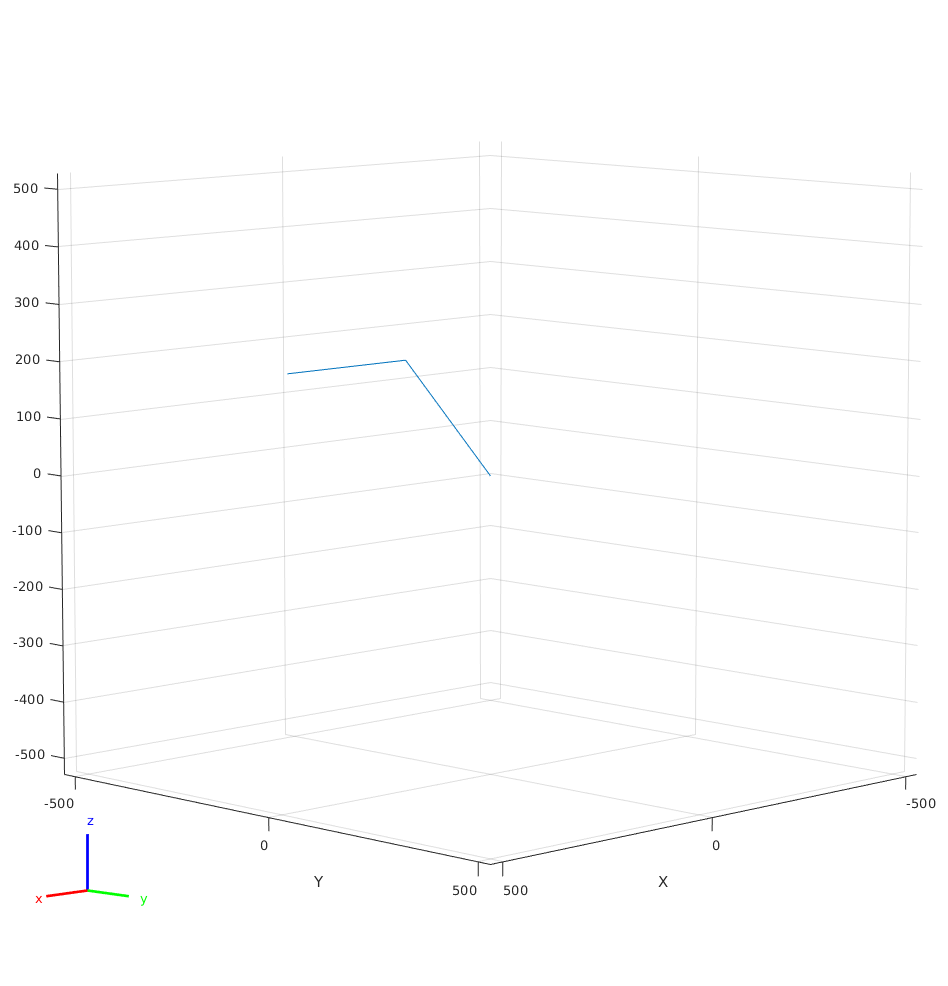

show(denso_robot);
axis on

### **Optional: Show different configuration**

As another optional section, here we edit the configuration of the robot to "move" it. First, we make a copy of the home configuration.

config = homeConfiguration(denso_robot);

Now, we can edit this configuration however we please. Let us set all the revolute joints to $\frac{\pi }{4}$, and the prismatic to -*100*.

config(1).JointPosition = pi/4;
config(2).JointPosition = pi/4;
config(3).JointPosition = -100;
config(4).JointPosition = pi/4;

Show configuration table.

config

config = 1×4 struct array with fields:
    JointName
    JointPosition


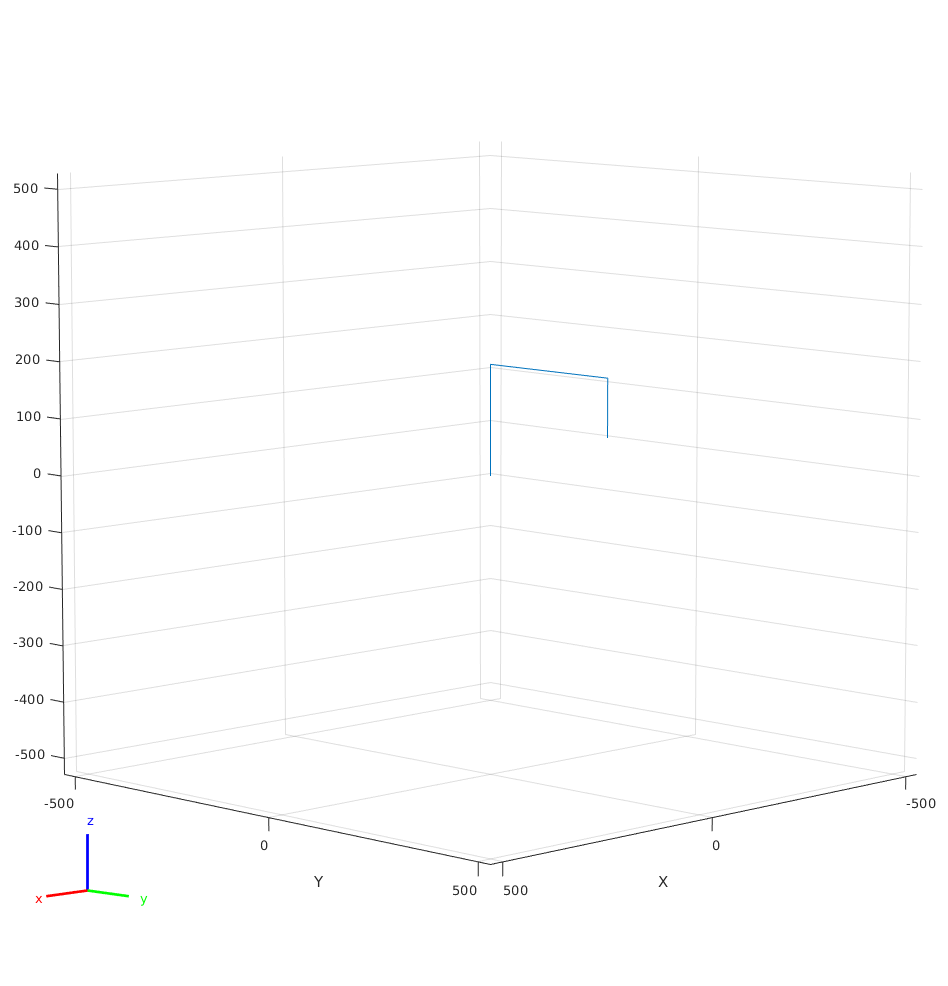

ax = show(denso_robot, config);
axis on

## *Show end-effector trajectory for given inputs*